L = 100;
Triangular_pulse = triang(L); %Pulso triangular de 100 muestras
Ep = sum(Triangular_pulse.*Triangular_pulse) %Energía del pulso

Ep = 33.3300

E1 = max(conv(Triangular_pulse,fliplr(Triangular_pulse))) %Máximo de la convolución

E1 = 33.3300

E2 = conv(Triangular_pulse,fliplr(Triangular_pulse));
E2(L) %Elemento 100 de la convolución

ans = 33.3300

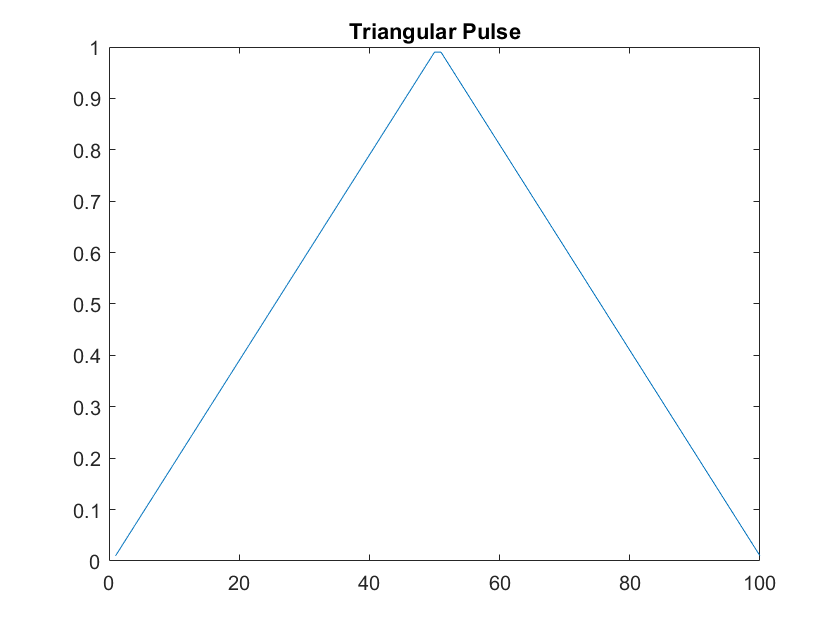

figure();
plot(Triangular_pulse);
title("Triangular Pulse");

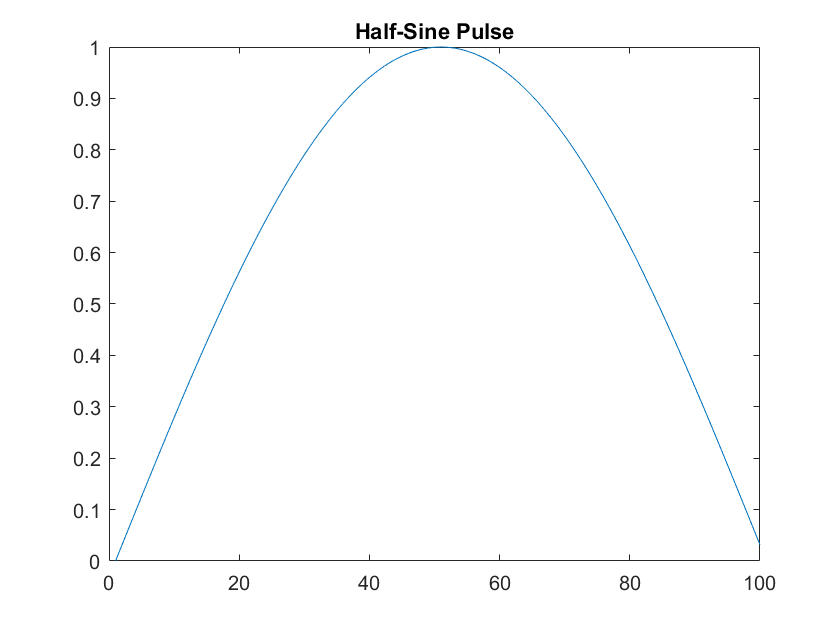

t_hs = 0:1/100:1-1/100;
f_hs = 0.5;
Half_sine_pulse = sin(2*pi*f_hs*t_hs);
Half_sine_pulse = Half_sine_pulse';
figure();
plot(Half_sine_pulse);
title("Half-Sine Pulse");

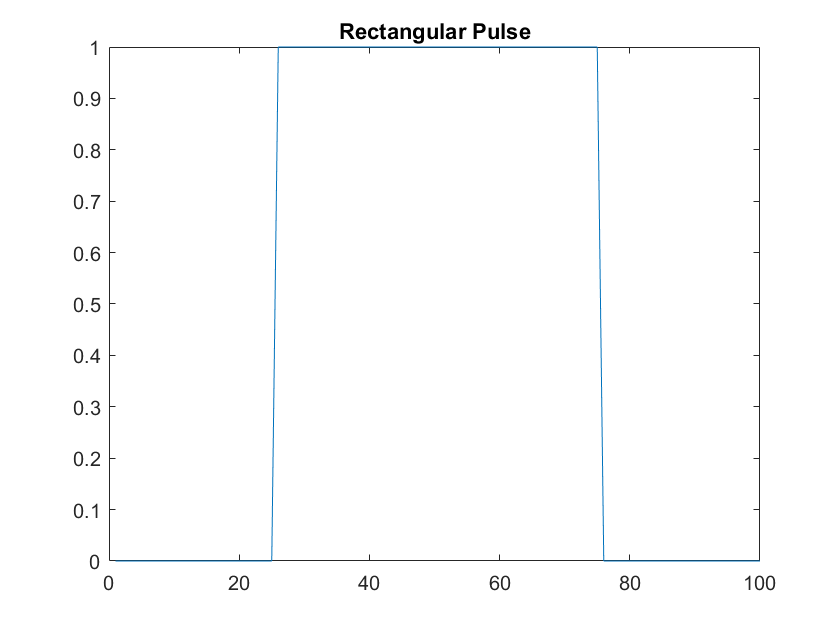

Rectangular_pulse = [zeros(1,100/4) ones(1,100/2) zeros(1,100/4)];
Rectangular_pulse = Rectangular_pulse';

figure();
plot(Rectangular_pulse);
title("Rectangular Pulse");

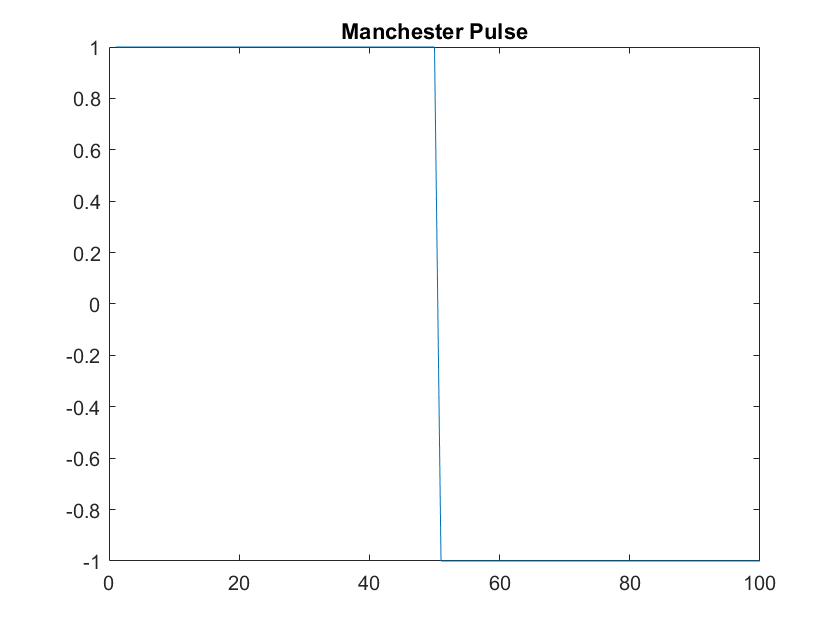

Manchester_pulse = [ones(1,100/2) -ones(1,100/2)];
Manchester_pulse = Manchester_pulse';
figure();
plot(Manchester_pulse);
title("Manchester Pulse");

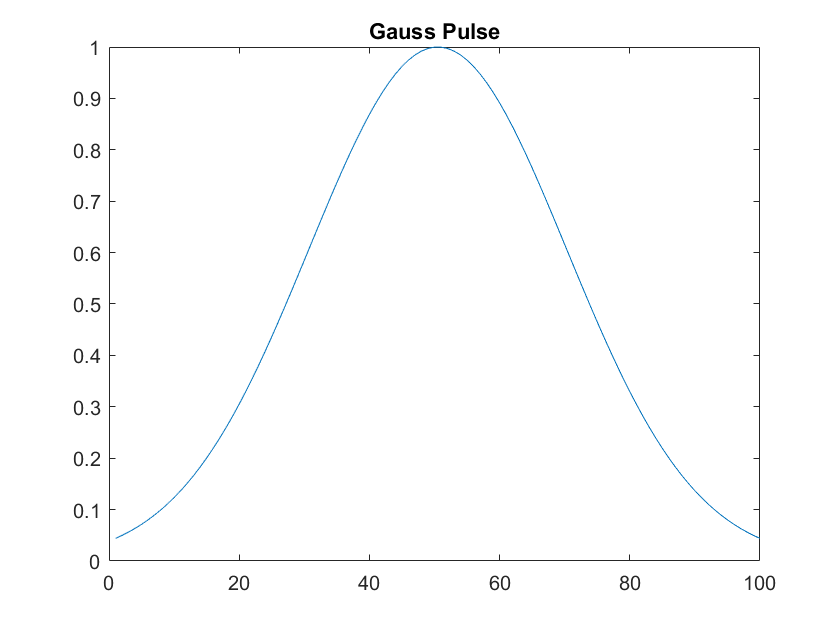

Gauss_pulse = gausswin(L);
figure();
plot(Gauss_pulse);
title("Gauss Pulse");

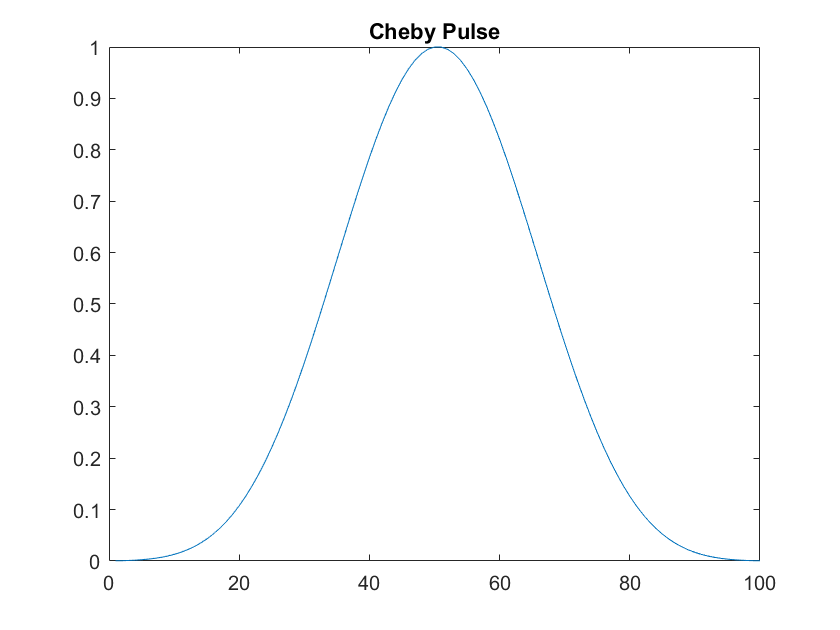

Cheby_pulse = chebwin(L);
figure();
plot(Cheby_pulse);
title("Cheby Pulse");

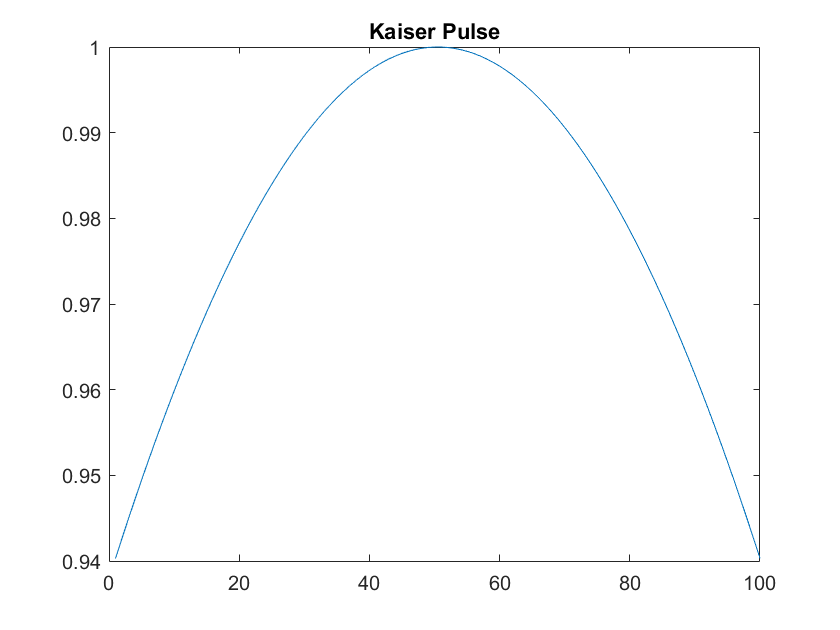

Kaiser_pulse = kaiser(L);
figure();
plot(Kaiser_pulse);
title("Kaiser Pulse");

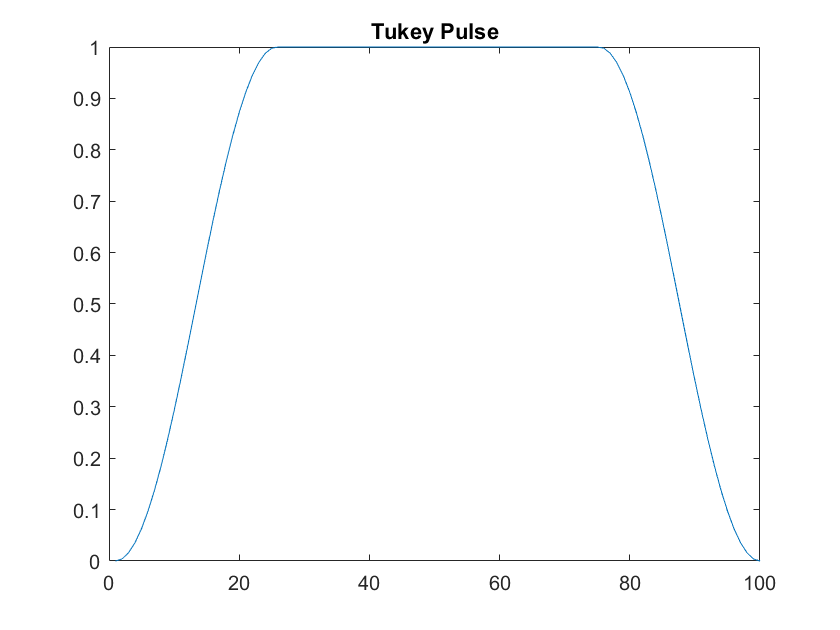

Tukey_pulse = tukeywin(L);
figure();
plot(Tukey_pulse);
title("Tukey Pulse");

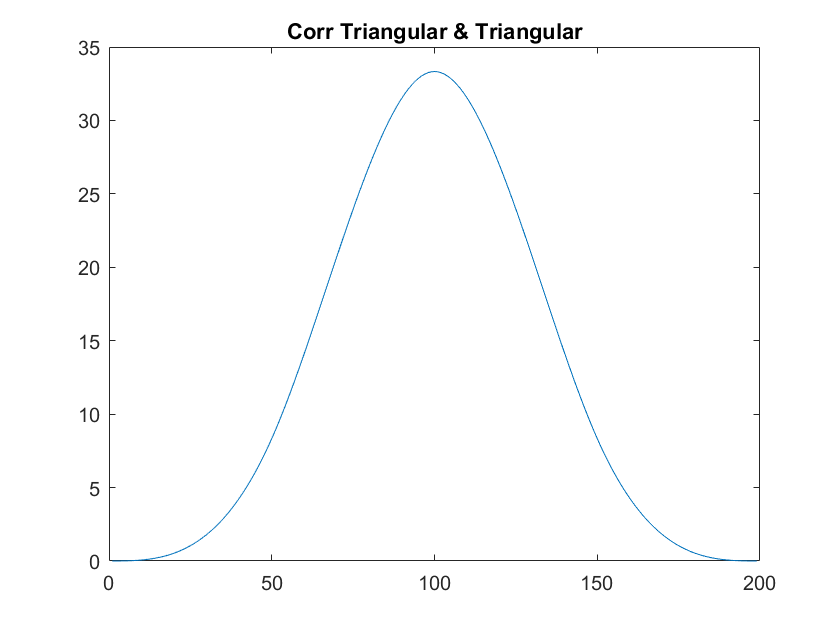




% Haciendo la correlación con el pulso triangular
Triangular_corr = xcorr(Triangular_pulse, Triangular_pulse);
figure;
plot(Triangular_corr);
title("Corr Triangular & Triangular");

max_Triangular_corr = max(Triangular_corr)

max_Triangular_corr = 33.3300

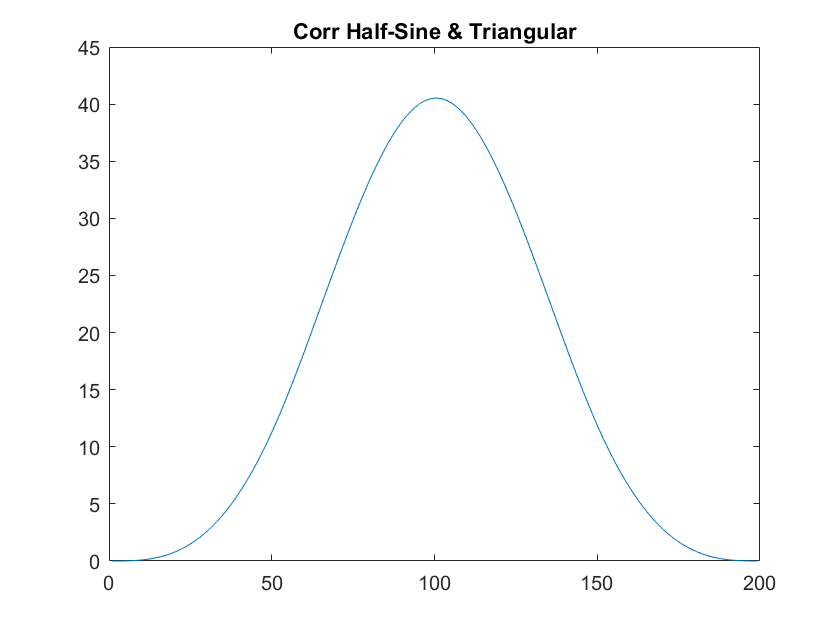

HalfSine_corr = xcorr(Half_sine_pulse, Triangular_pulse);
figure;
plot(HalfSine_corr);
title("Corr Half-Sine & Triangular");

max_HalfSine_corr = max(HalfSine_corr)

max_HalfSine_corr = 40.5218

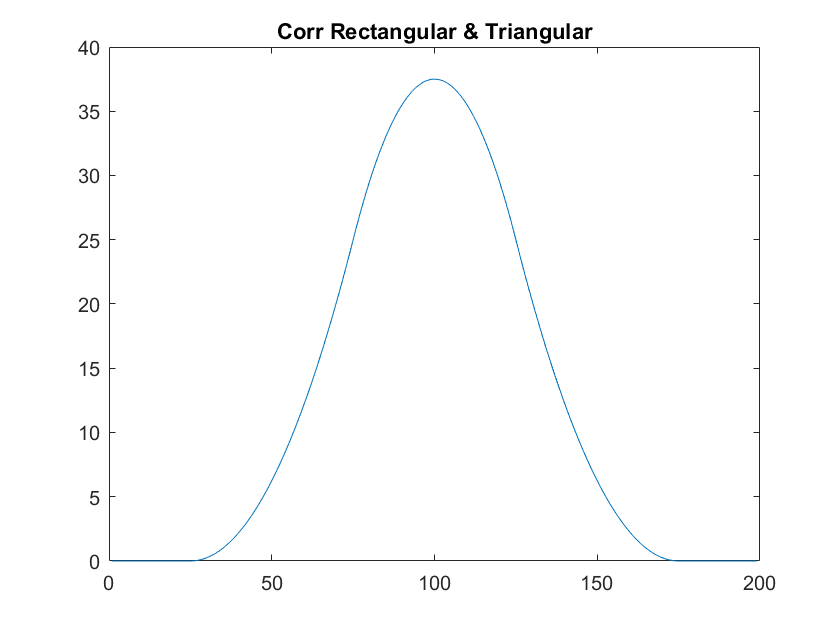

Rectangular_corr = xcorr(Rectangular_pulse, Triangular_pulse);
figure;
plot(Rectangular_corr);
title("Corr Rectangular & Triangular");

max_Rectangular_corr = max(Rectangular_corr)

max_Rectangular_corr = 37.5000

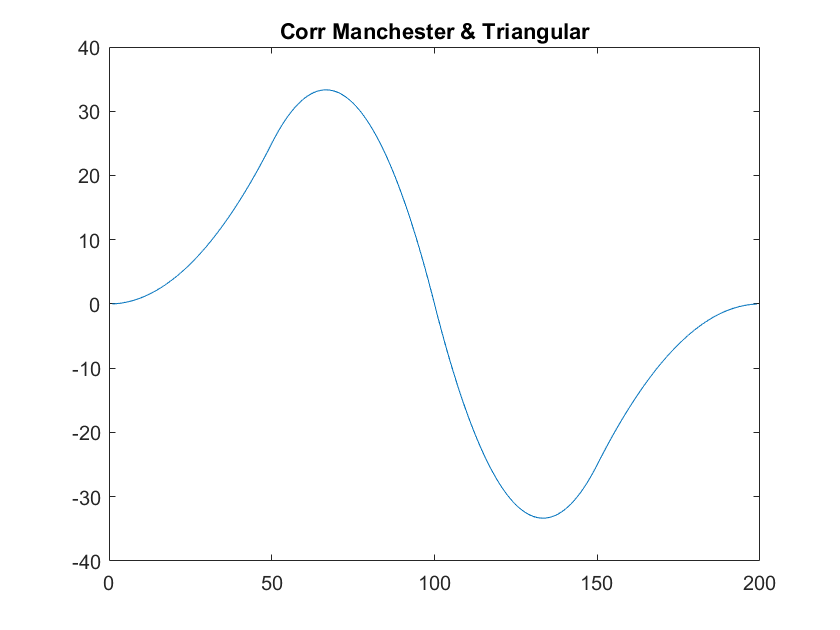

Manchester_corr = xcorr(Manchester_pulse, Triangular_pulse);
figure;
plot(Manchester_corr);
title("Corr Manchester & Triangular");

max_Manchester_corr = max(Manchester_corr)

max_Manchester_corr = 33.3300

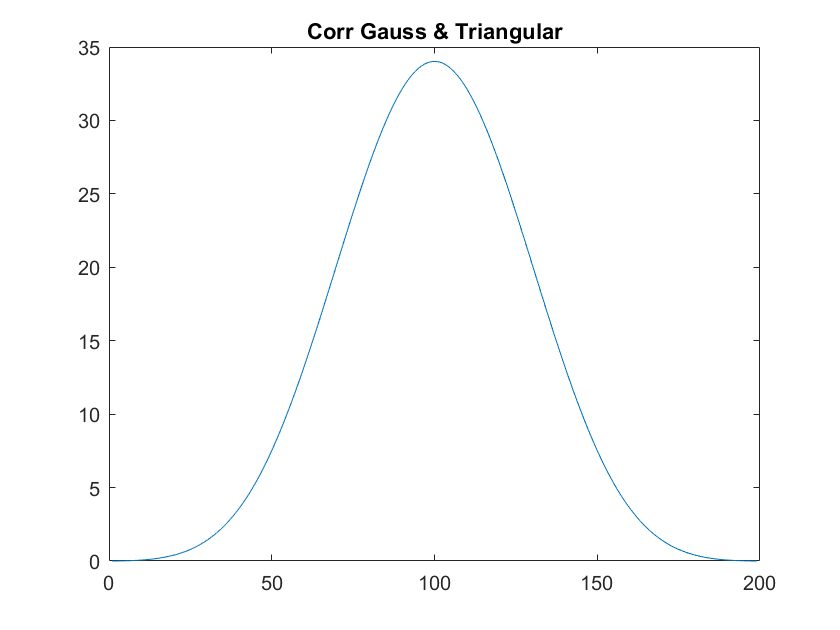

Gauss_corr = xcorr(Gauss_pulse, Triangular_pulse);
figure;
plot(Gauss_corr);
title("Corr Gauss & Triangular");

max_Gauss_corr = max(Gauss_corr)

max_Gauss_corr = 34.0209

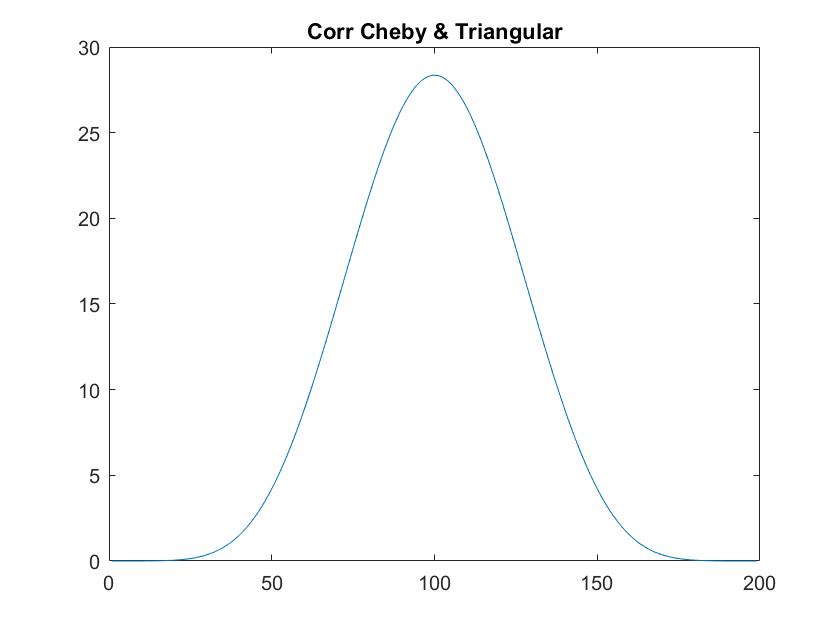

Cheby_corr = xcorr(Cheby_pulse, Triangular_pulse);
figure;
plot(Cheby_corr);
title("Corr Cheby & Triangular");

max_Cheby_corr = max(Cheby_corr)

max_Cheby_corr = 28.3560

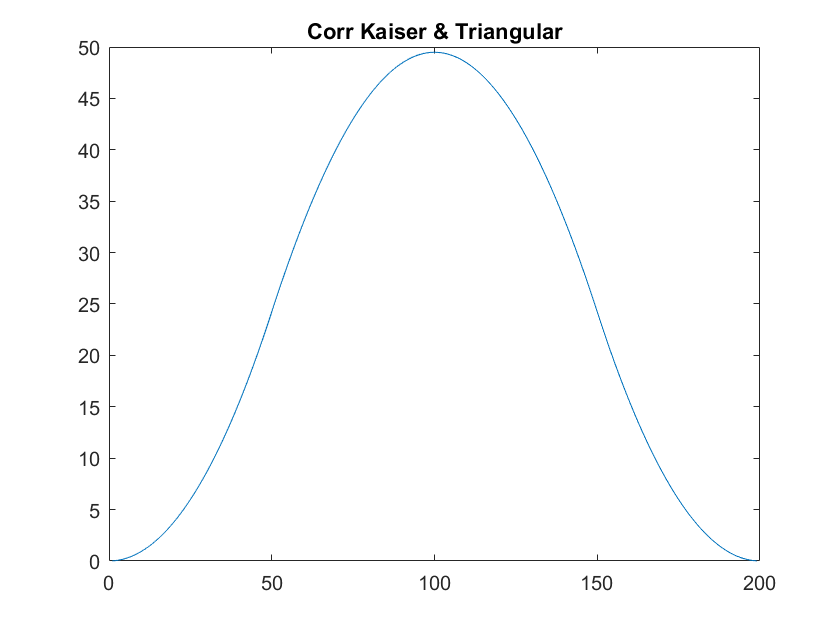

Kaiser_corr = xcorr(Kaiser_pulse, Triangular_pulse);
figure;
plot(Kaiser_corr);
title("Corr Kaiser & Triangular");

max_Kaiser_corr = max(Kaiser_corr)

max_Kaiser_corr = 49.4877

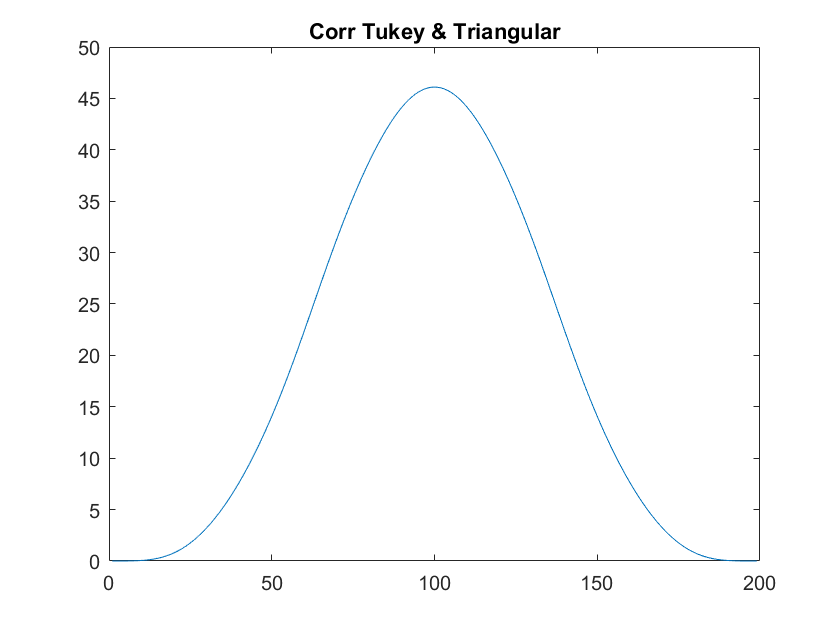

Tukey_corr = xcorr(Tukey_pulse, Triangular_pulse);
figure;
plot(Tukey_corr);
title("Corr Tukey & Triangular");

max_Tukey_corr = max(Tukey_corr)

max_Tukey_corr = 46.1028